clear; clc; close all

width = 1.5 ; % Line thickness
lsize = 12 ; tsize = 14 ; legsize = 9 ; msize = 8 ; % Font size in plots, label, title, legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');

% COLOURS - MaTLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
gamma = 1.4;
Machs = [1.4:0.1:2.2];
Spacings = [0.25,0.3,0.35,0.4,0.45,0.5,0.55,0.6,0.65,0.7,0.8,0.9];
Mach_array = repmat(Machs,length(Spacings),1)

Mach_array =     1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000


[X,Y] = meshgrid(Machs,Spacings);

%CdWave = X.*exp(-X.^2-Y.^2);
CdWave =[0.13372300	0.13028900	0.12843600	0.12571900	0.12430100	0.12184200	0.12174800	0.00233426	0.00358751;
0.12279100	0.12024500	0.11735400	0.11616500	0.11391800	0.00329463	0.00587150	0.00512922	0.00373783;
0.11516700	0.11282700	0.10999800	0.10870100	0.00471196	0.00547467	0.00350509	0.00219628	0.00170952;
0.10908500	0.10637700	0.10486200	0.10309300	0.00469977	0.00252141	0.00201319	0.00296174	0.00408375;
0.10352000	0.10115000	0.09981180	0.00535090	0.00217566	0.00292894	0.00447685	0.00606766	0.00756879;
0.09898930	0.09674000	0.09506661	0.00245183	0.00380087	0.00588249	0.00792598	0.00974116	0.01128010;
0.09428540	0.09220460	0.00427997	0.00408049	0.00680191	0.00942348	0.01162840	0.01346520	0.01501310;
0.09064270	0.08857450	0.00371171	0.00699493	0.01033840	0.01309540	0.01533910	0.01716340	0.01875940;
0.08805110	0.08629830	0.00615269	0.01039850	0.01399980	0.01678430	0.01900980	0.02089040	0.02047060;
0.08540880	0.00431752	0.00917551	0.01404110	0.01767750	0.02047610	0.02264410	0.02170960	0.02045660;
0.08196310	0.00900950	0.01614780	0.02131250	0.02501000	0.02483000	0.02313210	0.02170760	0.02046580;
0.08087570	0.01502350	0.02336090	0.02856780	0.02684870	0.02486010	0.02318650	0.02173330	0.02048350];

SE_mach = [1.5:0.05:3];
SE_spacing=[0.696848394612616	0.624018902807896	0.574437370296847	0.536339761404734	0.505435121076720	0.479528075073280	0.457313106907919	0.437941590787722	0.420827709590020	0.405548919163916	0.391789984797376	0.379309319360286	0.367917655096641	0.357463957271552	0.347825798661879	0.338902592132079	0.330610715820032	0.322879927339282	0.315650677490796	0.308872065143030	0.302500257775742	0.296497255905850	0.290829915282950	0.285469164925307	0.280389375773959	0.275567846481751	0.270984381230620	0.266620940532644	0.262461350413682	0.258491058674922	0.254696929399754];
SE_cdwave=[0.00540180831143633	0.00348512691122524	0.00271479570242097	0.00231847225491693	0.00208484633768729	0.00193028178409035	0.00181707088335272	0.00172702771107487	0.00165099127089367	0.00158417754531776	0.00152399126914087	0.00146895683288993	0.00141818321092438	0.00137109150175758	0.00132727424995320	0.00128642187567879	0.00124828367616215	0.00121264681494752	0.00117932475561279	0.00114815069843021	0.00111897369186704	0.00109165618943561	0.00106607239824355	0.00104210706976150	0.00101965454516384	0.000998617954220112	0.000978908513325865	0.000960444893344379	0.000943152641420034	0.000926963648143081	0.000911815655154128];

foam_mach = [1.5,1.6,1.7,1.8,2,2.2,2.4,2.6,2.8,3];
foam_cdwave = [0.00401168,0.00265670,0.00215534,0.00188625,...
0.00153404,0.00143431,0.00133589,0.00127382,0.00125071,0.00118717]

foam_cdwave =     0.0040    0.0027    0.0022    0.0019    0.0015    0.0014    0.0013    0.0013    0.0013    0.0012


foam_spacing=[0.6968,0.5744,0.5054,0.4573,0.3918,0.3478,0.3157,0.2908,0.2710,0.2547];
foam_cellcount = [21140,21404,21388,21156,21514,21026,21248,21346,21178,21284];

viewangle = [55 50]

viewangle =     55    50


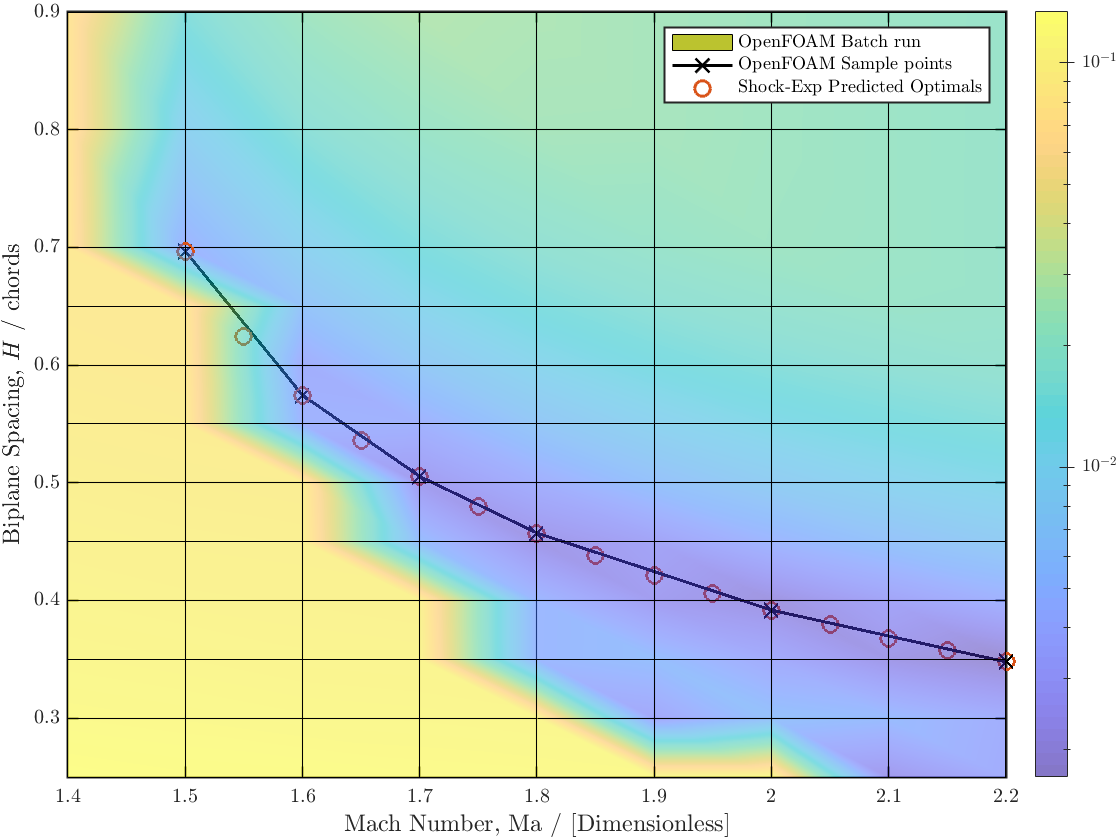


figure
surf(X,Y,CdWave,'FaceColor','interp','FaceAlpha',0.5)
grid on; box on; hold on
%title("\textbf{Wave Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Total Drag Coefficient, $C_{D_\textrm{Total}}$ / [Unit planform]",'FontSize',lsize)
InSet = get(gca, 'TightInset');
set(gca,'ColorScale','log')
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
hold on
plot3(foam_mach,foam_spacing,foam_cdwave,'kx-',"LineWidth",1.5,"MarkerSize",msize)
plot3(SE_mach,SE_spacing,SE_cdwave,'o',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
legend('OpenFOAM Batch run','OpenFOAM Sample points','Shock-Exp Predicted Optimals','location','northeast','FontSize',legsize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / chords",'FontSize',lsize)
%title([{"\textbf{SE Predicted Optimal Spacing contrasted with OpenFOAM Design Space}"}],'FontSize',tsize)
%ylim([0,1])
xlim([1.4, 2.2])
ylim([0.25, 0.9])
view([0 90])
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]); grid on; box on;hold off
hold off
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
%set(c, 'ylim', [-0.25 0.5]); % set your range here
%colormap(cmap); % apply new colormap
fudge = 1.8; alfa =fudge*0.35; %make it a bit darker for visuals
c.Colormap=((alfa*c.Colormap)+((1-alfa)*[1,1,1]));
ylabel(c,"$C_{D_\textrm{Wave}}$ per wing area / [Unit planform]",'Interpreter','latex','FontSize',lsize)
H=gca; H.LineWidth=1;

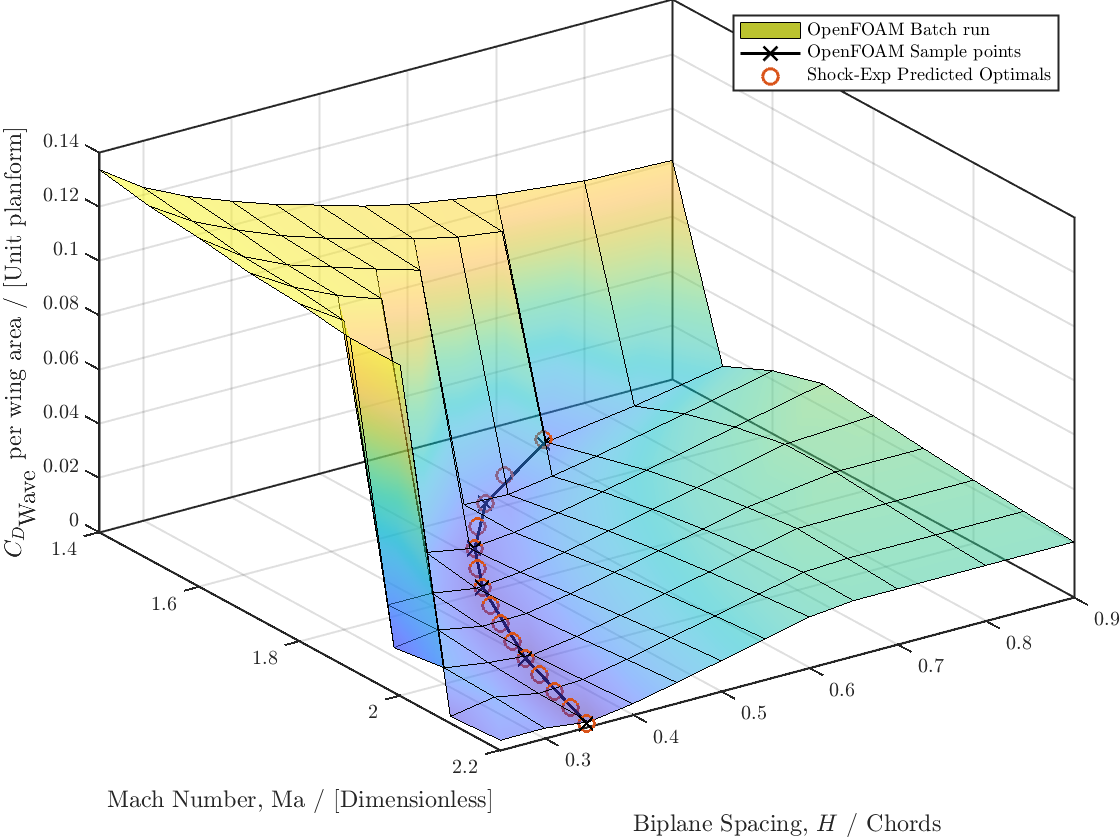


figure
surf(X,Y,CdWave,'FaceColor','interp','FaceAlpha',0.5)
grid on; box on; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("$C_{D_\textrm{Wave}}$ per wing area / [Unit planform]",'FontSize',lsize)
InSet = get(gca, 'TightInset');
set(gca,'ColorScale','log')
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
hold on
plot3(foam_mach,foam_spacing,foam_cdwave,'kx-',"LineWidth",1.5,"MarkerSize",msize)
plot3(SE_mach,SE_spacing,SE_cdwave,'o',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
legend('OpenFOAM Batch run','OpenFOAM Sample points','Shock-Exp Predicted Optimals','location','northeast','FontSize',legsize)
%title("\textbf{SE Predicted Optimal Spacing contrasted with OpenFOAM Design Space}",'FontSize',tsize)
%ylim([0,1])
xlim([1.4, 2.2])
ylim([0.25, 0.9])
view([55 35])
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]); grid on; box on;hold off
hold off
H=gca; H.LineWidth=1;

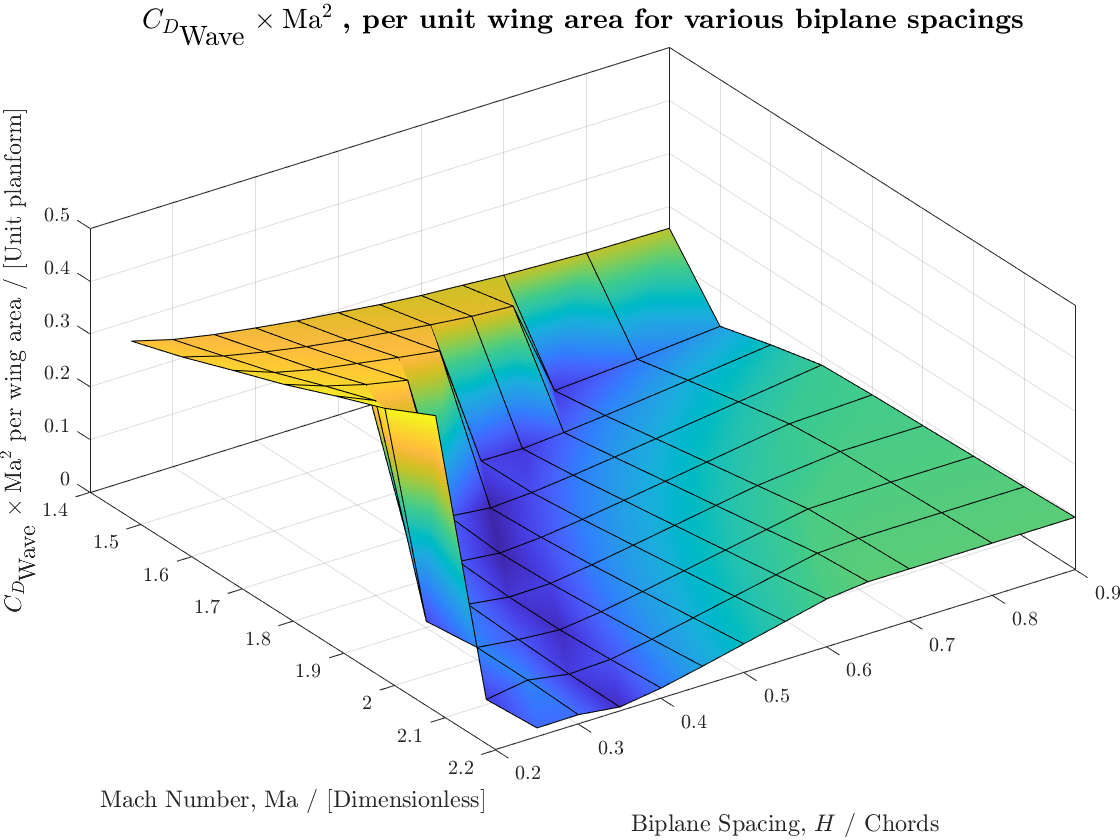


dynamic_head = (Mach_array.^2); %(gamma/2)*P.*
DWave = CdWave.*dynamic_head; %per area

surf(X,Y,DWave,'FaceColor','interp')
grid on; box on; hold on
title("$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ \textbf{, per unit wing area for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ per wing area / [Unit planform]",'FontSize',lsize)
ylim([0.2 0.9])
xlim([1.4 2.2])
view(viewangle)
InSet = get(gca, 'TightInset');
set(gca,'ColorScale','log')
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
hold off


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## multi dimensional

Machs = [1.4:0.1:2.2];
Spacings = [0.25,0.3,0.35,0.4,0.45,0.5,0.55,0.6,0.65,0.7,0.8,0.9];
%Staggers = [0,0.05,0.1,0.15,0.2,0.25];
Staggers = [0,0.1,0.2];
Angles = [0,1,3];

Mach_array = repmat(Machs,length(Spacings),1)

Mach_array =     1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000
    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000


[X,Y,Z] = meshgrid(Machs,Spacings,Staggers);
%drags = cat(3,DWave,1.1*DWave,1.2*DWave,1.5*DWave,2*DWave,2.5*DWave)
drags = cat(3,DWave,1.2*DWave,2*DWave)

drags = drags(:,:,1) =

    0.2621    0.2932    0.3288    0.3633    0.4027    0.4398    0.4870    0.0103    0.0174
    0.2407    0.2706    0.3004    0.3357    0.3691    0.0119    0.0235    0.0226    0.0181
    0.2257    0.2539    0.2816    0.3141    0.0153    0.0198    0.0140    0.0097    0.0083
    0.2138    0.2393    0.2684    0.2979    0.0152    0.0091    0.0081    0.0131    0.0198
    0.2029    0.2276    0.2555    0.0155    0.0070    0.0106    0.0179    0.0268    0.0366
    0.1940    0.2177    0.2434    0.0071    0.0123    0.0212    0.0317    0.0430    0.0546
    0.1848    0.2075    0.0110    0.0118    0.0220    0.0340    0.0465    0.0594    0.0727
    0.1777    0.1993    0.0095    0.0202    0.0335    0.0473    0.0614    0.0757    0.0908
    0.1726    0.1942    0.0158    0.0301    0.0454    0.0606    0.0760    0.0921    0.0991
    0.1674    0.0097    0.0235    0.0406    0.0573    0.0739    0.0906    0.0957    0.0990
    0.1606    0.0203    0.0413    0.0616    0.0810    0.0896    0.

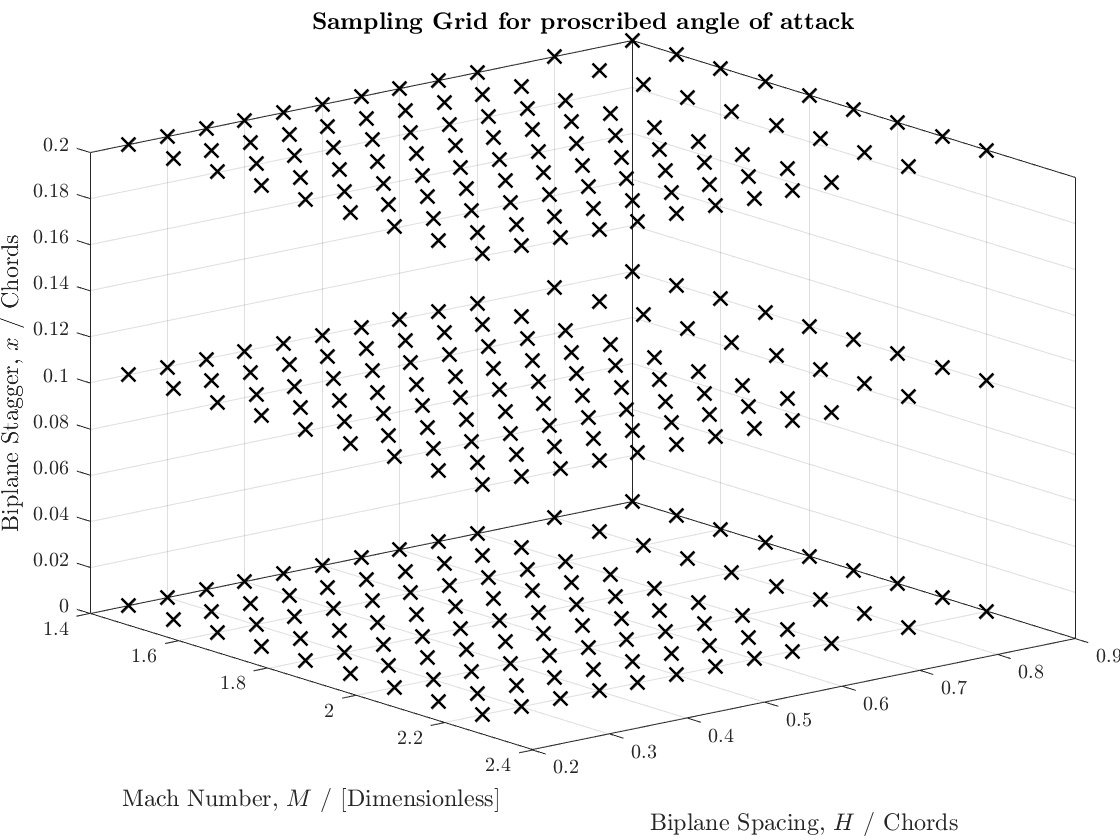


for i =1:length(Staggers)
plot3(X(:,:,i),Y(:,:,i),Z(:,:,i),'kx','LineWidth',width,'MarkerSize',msize)    % draw the scatter plot
hold on
end
grid on; box on; hold on
title("\textbf{Sampling Grid for proscribed angle of attack}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
%ylim([0.2 0.9])
%zlim([0 8000])
%xlim([1.4 2.2])
view(viewangle)
view([72.134 52.632])
%InSet = get(gca, 'TightInset');
%set(gca,'ColorScale','log')
%set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
hold off

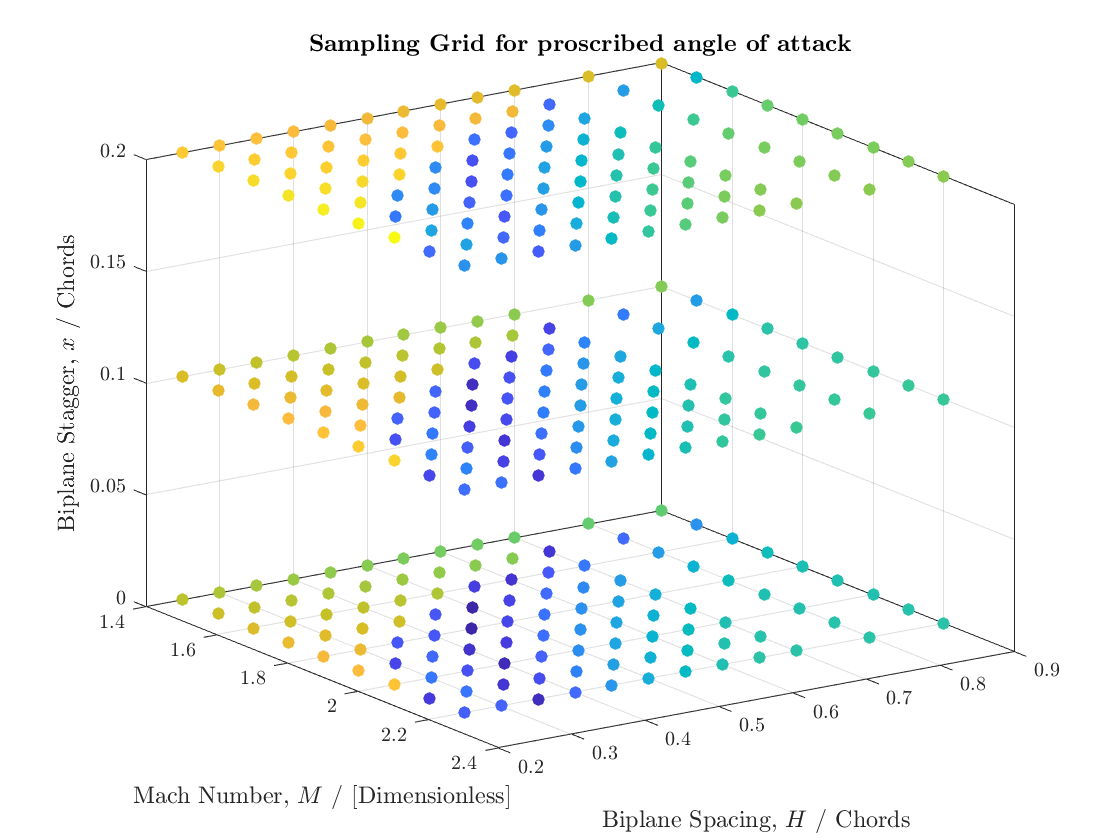


figure
for j =1:length(Spacings)
for i =1:length(Staggers)
scatter3(X(j,:,i),Y(j,:,i),Z(j,:,i),40,log(drags(j,:,i)),'filled')    % draw the scatter plot
hold on
end 
end
grid on; box on; hold on
title("\textbf{Sampling Grid for proscribed angle of attack}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view([72.134 52.632])
hold off

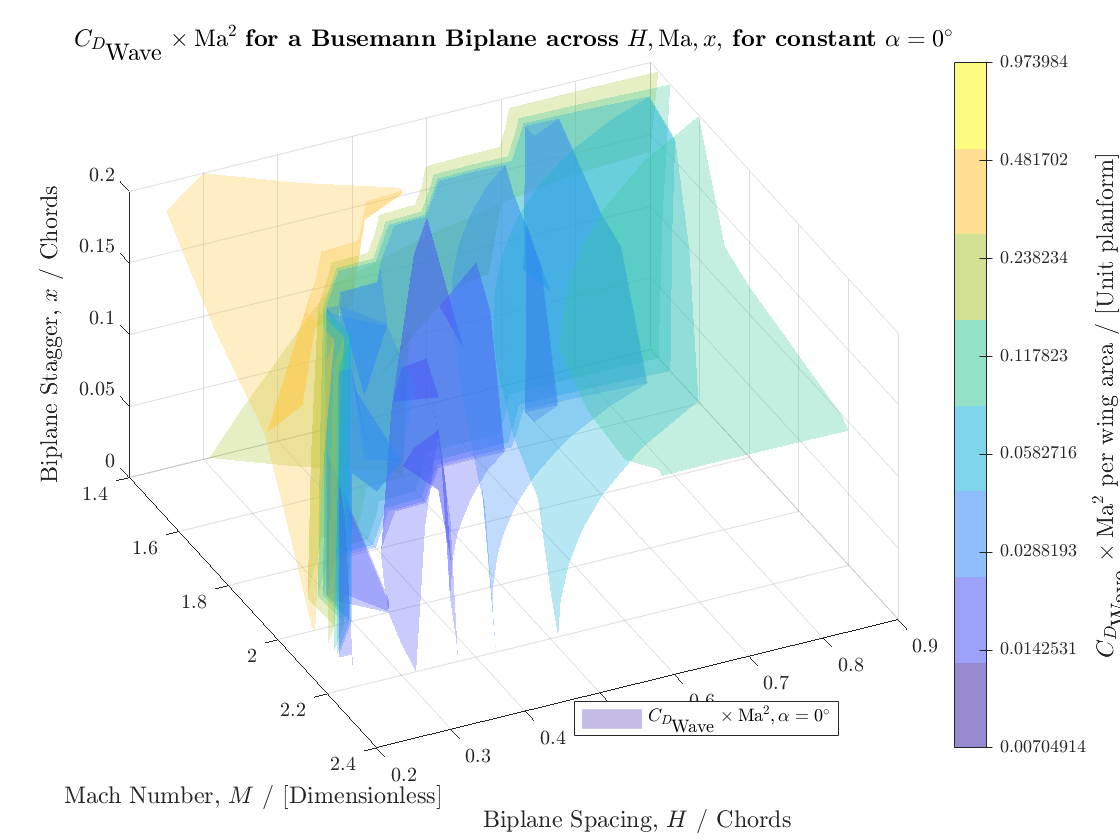


% cdwave=c;
% % Assign data to the grid point
% cq = nan(size(X));
% [~, pos] = ismember([x,y,z],[X(:),Y(:),Z(:)],'rows');
% cq(pos) = cdwave; %c is a matrix of colours (i.e. cdwave values)

% Find boundary points location
%k = boundary(x,y,z,1);

% Create isosurface levels and color

% Visualize the result
figure;%clf;
numcolours = 8; color = parula(numcolours); %color = jet(N);
lower_index=min(drags,[],'all'); upper_index=max(drags,[],'all');
levels = logspace(log10(lower_index),log10(upper_index),numcolours);

% set(gcf,'Visible','on')
hold on; alfa=0.3;
for i = 1:numcolours
    p = patch(isosurface(X,Y,Z,drags,levels(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    alfa);
    isonormals(X,Y,Z,drags,p)
end
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view([72.134 52.632]); grid on
%camlight('top')%headlight
lighting gouraud
%colormap(parula(numcolours));
%set(gca,'ColorScale','log')
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both','Ticks',linspace(0,1,numcolours),'TickLabels',levels)%,'Limits'),[lower_index,upper_index])

%c.Ruler.Scale='log'
fudge = 1.8; alfa =fudge*alfa; %make it a bit darker for visuals
c.Colormap=((alfa*color)+((1-alfa)*[1,1,1]));
ylabel(c,'$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
%title({'$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ \textbf{for a Busemann Biplane across} $H,\textrm{Ma},x$','\textbf{For constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
title({'$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ \textbf{for a Busemann Biplane across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
legend('$C_{D_\textrm{Wave}}\times\textrm{Ma}^2, \alpha=0^{\circ}$','Location','best')
hold off

## Runtime and style calcs

t_ramp = 10; t_hold = 25;
%time for one run to 25secs
t_single_real = 4500*(t_hold/25); %seconds for a 25 second sim
lowest_speed = 1.2; %Mach AND m/s
domain_rad = 6;
t_cross_real = domain_rad/lowest_speed; %call it 10sec to be safe

t_inbetween_real = 4500*t_ramp/25;
t_onespeed = t_ramp+t_hold;
t_onespeed_real = t_single_real+t_cross_real;

Machs_mod = [1.2,1.3,1.4,1.5,1.6,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5];
%Machs_mod = [0.3:0.1:2.5]
Spacings_mod = [0.25,0.375,0.5,0.625,0.75];
Staggers_mod = [-0.5,-0.25,-0.1,0,0.1,0.25,0.5];
Angles_mod = [0,1,3];

[X,Y,Z]=meshgrid(Machs_mod,Spacings_mod,Staggers_mod);
point.Mach=X

point = struct with fields:
    Mach: [5×14×7 double]


point.Spacing=Y

point = struct with fields:
       Mach: [5×14×7 double]
    Spacing: [5×14×7 double]


point.Stagger=Z

point = struct with fields:
       Mach: [5×14×7 double]
    Spacing: [5×14×7 double]
    Stagger: [5×14×7 double]


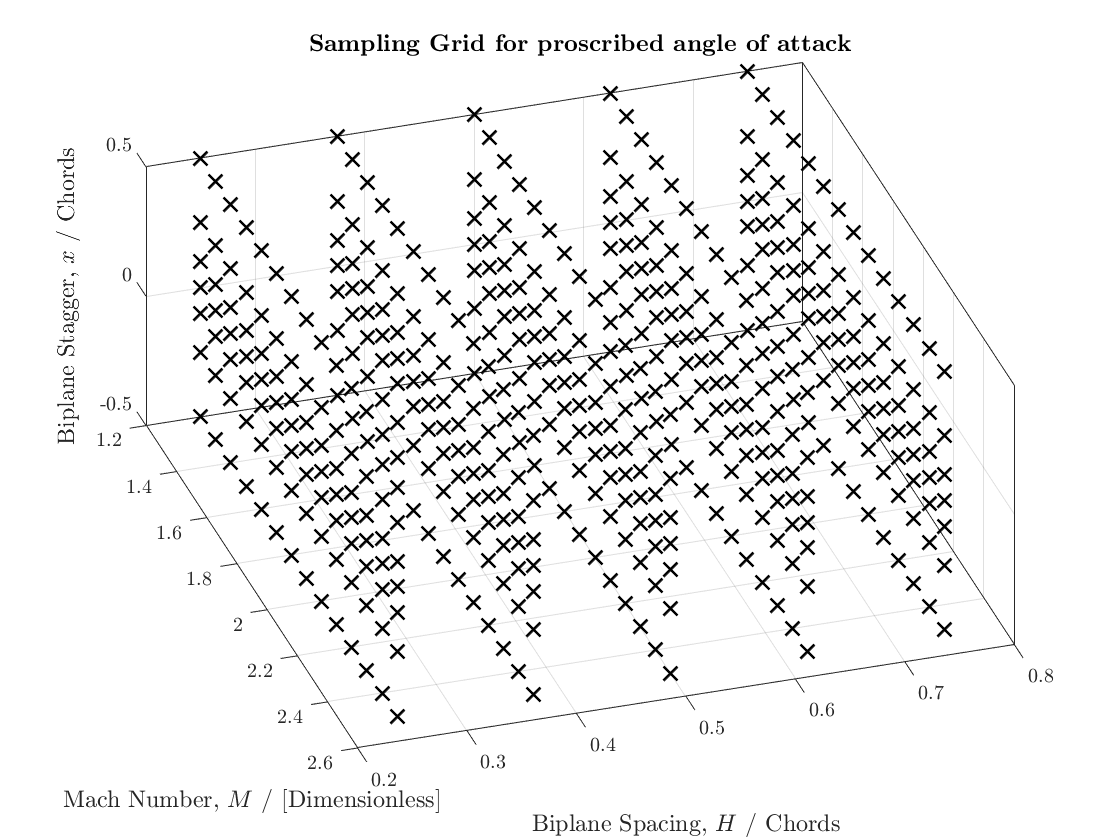

figure
for i =1:length(Staggers_mod)
plot3(X(:,:,i),Y(:,:,i),Z(:,:,i),'kx','LineWidth',width,'MarkerSize',msize)    % draw the scatter plot
hold on
end
grid on; box on; hold on
title("\textbf{Sampling Grid for proscribed angle of attack}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
%ylim([0.2 0.9])
%zlim([0 8000])
%xlim([1.4 2.2])
view([72.134 52.632])
%InSet = get(gca, 'TightInset');
%set(gca,'ColorScale','log')
%set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
hold off


num_cases_oneAngle = length(Spacings_mod)*(length(Staggers_mod))

num_cases_oneAngle = 35

num_data_oneAngle = num_cases_oneAngle*length(Machs_mod)

num_data_oneAngle = 490

num_cases_allAngle = num_cases_oneAngle*length(Angles_mod)

num_cases_allAngle = 105

num_data_allAngle = num_cases_allAngle*length(Machs_mod)

num_data_allAngle = 1470


t_run_real = length(Machs_mod)*t_onespeed_real;
hrs_runs = t_run_real/3600

hrs_runs = 17.5194

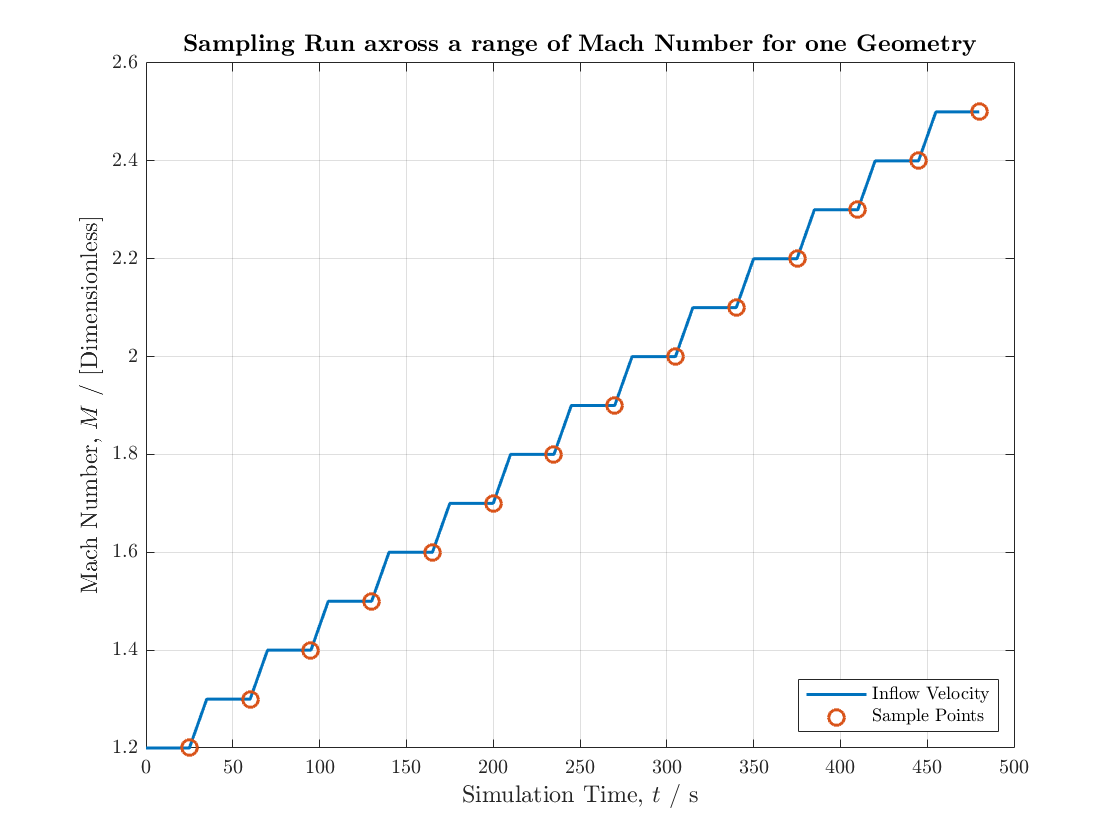


Machs_all = reshape( cat( 1, [Machs_mod], [Machs_mod] ), 1, [] );
t_all = zeros(size(Machs_all));
for i=1:((2*length(Machs_mod)))
    t_all(i)= floor(i/2)*t_hold+floor(i/2-1/2)*t_ramp;
end

t_sampling=t_all(2:2:end);         

figure
plot(t_all,Machs_all,'-','LineWidth',width,'MarkerSize',msize)
hold on
plot(t_sampling,Machs_mod,'o','LineWidth',width,'MarkerSize',msize)
grid on; box on; hold on
title("\textbf{Sampling Run axross a range of Mach Number for one Geometry}",'FontSize',tsize)
ylabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
xlabel("Simulation Time, $t$ / s",'FontSize',lsize)
legend('Inflow Velocity', 'Sample Points','Location',"southeast")
hold off

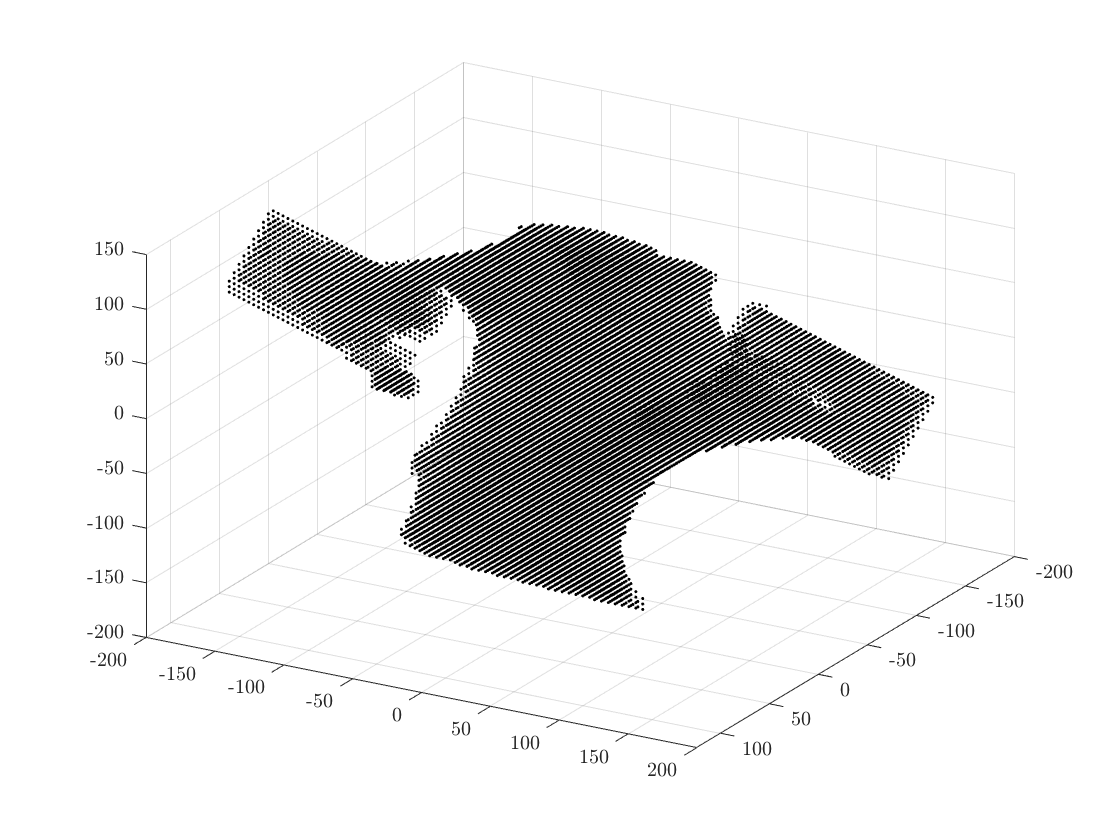

%https://uk.mathworks.com/matlabcentral/answers/486187-4d-plot-in-order-to-create-a-surface-with-density-from-4-vectors-coordinates-of-the-dots-x-y-z
% Load data
load('object.mat')
figure
plot3(x,y,z,'k.','MarkerSize',0.5)
view(120,30); grid on
hold off

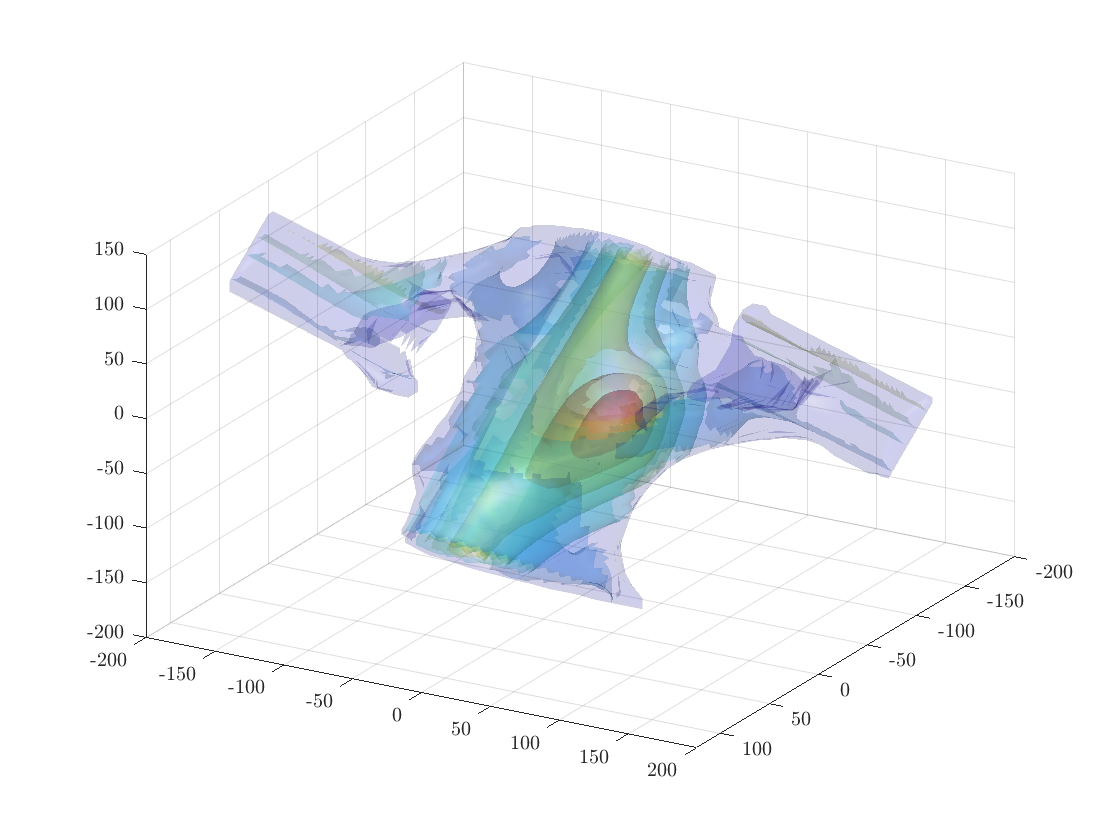


cdwave=c;
% Create meshgrid
[X, Y, Z] = meshgrid(min(x):5:max(x),min(y):5:max(y),min(z):5:max(z));

% Assign data to the grid point
cq = nan(size(X));
[~, pos] = ismember([x,y,z],[X(:),Y(:),Z(:)],'rows');
cq(pos) = cdwave; %c is a matrix of colours (i.e. cdwave values)

% Find boundary points location
k = boundary(x,y,z,1);

% Create isosurface levels and color
numlayers = 8; color = jet(numlayers); %color = jet(N);
v = linspace(min(cdwave),max(cdwave),numlayers);

% Visualize the result
figure; hold on
for i = 1:numlayers
    p = patch(isosurface(X,Y,Z,cq,v(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    0.2);
    isonormals(X,Y,Z,cq,p)
end
%this trisurface adds the external wrapping layer
trisurf(k,x,y,z,... 
    'Facecolor',     'b',... %was 'b', this repeats a colour
    'FaceAlpha',    0.1,...
    'Edgecolor',    'none')
view(120,30); grid on
camlight('headlight')
lighting gouraud